# KUNCI Praktikum 3 - Shift 1 Selasa

`28 September 2021`

`Nama : `**Asisten Praktikum **

`NIM  :`

## **Nomor 1**

Sebutkan dan jelaskan keuntungan dari menyelesaikan SPL menggunakan metode dekomposisi $LU$ dibandingkan dengan metode Gauss-Seidel !

#### Jawaban :

Metode dekomposisi Gauss-Seidel bisa tidak konvergen ke suatu solusi apabila matriks yang di dekomposisi tidak dominan diagonal. Berbeda dengan dekomposisi $LU$ yang lebih stabil. 

Selain itu, apabila kita sedang bekerja dengan banyak sekali sistem SPL berbentuk $Ax=B$ dengan $B$ yang berubah-ubah dan $A$ tetap, maka penggunaan dekomposisi $LU$ akan jauh lebih efisien dibandingkan dengan Gauss-Seidel karena kita hanya cukup menentukan $A=LU$ sekali saja. 

## **Nomor 2**

Matriks Walsh (atau Matriks Hadamard terurut-alami) adalah sebuah keluarga matriks berukuran $2^n \times 2^n$ yang digunakan untuk menghitung *Walsh-Hadamard Transform, *sebuah prosedur varian dari *Discrete Fourier Transform,* yang mempunyai banyak kegunaan dalam *signal processing *dan *quantum computing.*

Matriks ini didefinisikan secara rekursif sebagai berikut:

#### 
$$W_1 =\left\lbrack \begin{array}{cc}
1 & 1\\
1 & -1
\end{array}\right\rbrack$$


#### 
$$W_m =\left\lbrack \begin{array}{cc}
W_{m-1}  & W_{m-1} \\
W_{m-1}  & -W_{m-1} 
\end{array}\right\rbrack ,m\ge 2$$


### 2A

Buatlah sebuah fungsi  `genWalshMatrix.m` yang menerima input bilangan asli $n$ dan mengembalikan matriks Walsh $W_n$.

% Run section untuk memeriksa jawaban anda.
n = 4;
genWalshMatrix(n)

ans =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1
     1     1    -1    -1     1     1    -1    -1     1     1    -1    -1     1     1    -1    -1
     1    -1    -1     1     1    -1    -1     1     1    -1    -1     1     1    -1    -1     1
     1     1     1     1    -1    -1    -1    -1     1     1     1     1    -1    -1    -1    -1
     1    -1     1    -1    -1     1    -1     1     1    -1     1    -1    -1     1    -1     1
     1     1    -1    -1    -1    -1     1     1     1     1    -1    -1    -1    -1     1     1
     1    -1    -1     1    -1     1     1    -1     1    -1    -1     1    -1     1     1    -1
     1     1     1     1     1     1     1     1    -1    -1    -1    -1    -1    -1    -1    -1
     1    -1     1    -1     1    -1     1    -1    -1     1    -1     1    -1     1    -1     1


### 2B 

Buatlah sebuah fungsi `doolittleLUDecomp.m` yang menerima input sebuah matriks persegi $A$ dan mengembalikan matriks  $L$`, `$U$ sehingga $A = LU$

% Run section untuk memeriksa jawaban anda. (Eh bentar, ini bisa di-run ga?
% Kodenya terlihat mencurigakan...jadi silahkan periksa baik-baik dulu, lalu koreksi!)

% Sebelum dikoreksi (pada naskah soal) :
% n = 8;
% A = genWalshMatrix(n);
% L, U = doolitleLUDecomp(A);
% L x U

% Setelah Koreksi :
n = 8;
A = genWalshMatrix(n);
[L, U] = doolittleLUDecomp(A);
disp(L*U)

  Columns 1 through 5
     1     1     1     1     1
     1    -1     1    -1     1
     1     1    -1    -1     1
     1    -1    -1     1     1
     1     1     1     1    -1
     1    -1     1    -1    -1
     1     1    -1    -1    -1
     1    -1    -1     1    -1
     1     1     1     1     1
     1    -1     1    -1     1
     1     1    -1    -1     1
     1    -1    -1     1     1
     1     1     1     1    -1
     1    -1     1    -1    -1
     1     1    -1    -1    -1
     1    -1    -1     1    -1
     1     1     1     1     1
     1    -1     1    -1     1
     1     1    -1    -1     1
     1    -1    -1     1     1
     1     1     1     1    -1
     1    -1     1    -1    -1
     1     1    -1    -1    -1
     1    -1    -1     1    -1
     1     1     1     1     1
     1    -1     1    -1     1
     1     1    -1    -1     1
     1    -1    -1     1     1
     1     1     1     1    -1
     1    -1     1    -1    -1
     1     1    -1    -1    -1
     1    -1    -

### 2C

Hitunglah determinan dari $W_2$ menggunakan hasil dekomposisi Doolittle-nya. Apakah matriks ini invertibel?

[L_2,U_2] = doolittleLUDecomp(genWalshMatrix(2));
% Diperoleh W_2 = L_2U_2 dimana keduanya adalah matriks diagonal.

% Memanfaatkan sifat det(W_2)=det(L_2)det(U_2) dan fakta bahwa determinan dari suatu matriks diagonal adalah hasil 
% perkalian semua entri diagonalnya, diperoleh
det_W2 = prod(diag(L_2))*prod(diag(U_2));
disp(det_W2)

    16


% Karena determinan W_2 > 0, maka matriks ini invertibel.

### 2D

Gunakan dekomposisi Doolittle untuk mencari solusi untuk $\vec{x}$ sehingga $W_2 \vec{x} =$$\left\lbrack \begin{array}{c}
1\\
\frac{1}{2}\\
\frac{1}{3}\\
\frac{1}{4}
\end{array}\right\rbrack \ldotp$ Buatlah sebuah fungsi `solveSPL.m` yang menerima input $A$ matriks koefisien dan $b$ vektor hasil, dan mengembalikan vektor $\vec{x}$solusi dari persamaan yang diberikan.

% Uncomment section ini, lalu lengkapi bagian kosong dari section ini dan jalankan (run section).

A = genWalshMatrix(2);
b = [1; 1/2; 1/3; 1/4];
x = solveSPL(A,b)

x =      5.208333333333333e-01
     1.458333333333333e-01
     2.291666666666667e-01
     1.041666666666667e-01


## Soal Bonus

### 2E

(Bonus kecil) Coba plot matriks $L$ atau $U$ menggunakan fungsi `imshow(L) `atau `imshow(U),` dari dekomposisi LDU (yang dapat dilakukan di soal 2F) dari matriks Walsh orde ke-8. 

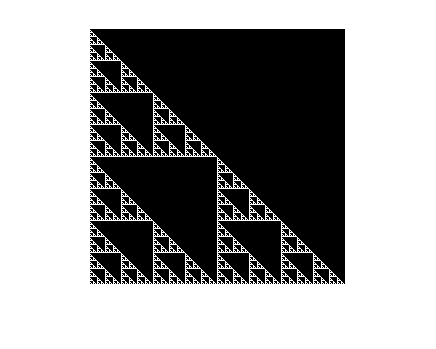

W8 = genWalshMatrix(8);
[L,U] = doolittleLUDecomp(W8);
[D, U_new] = genDforLDU(L,U);
imshow(L)

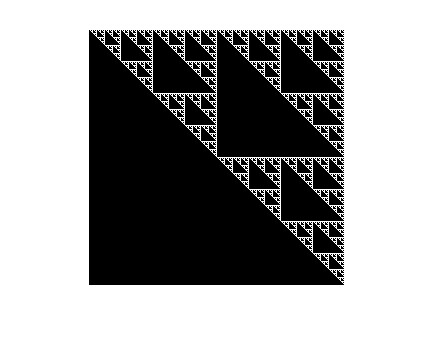

imshow(U_new)

Apakah hasil plot mengingatkan Anda terhadap sebuah objek matematika/geometris tertentu? Sebutkan namanya/tipe objeknya.

% Segitiga Sierpinski !

### 2F

(Bonus sedang) Buatlah sebuah fungsi **genDforLDU.m** yang menerima input matriks $L$, $U$ yang telah Anda bangun dengan dekomposisi Doolittle, dan mengembalikan matriks $D$ dan $U_{new}$ sehingga $D*U_{new}=U$  dan diagonal $U_{new}$ semua bernilai 1 (sehingga kita peroleh matriks diagonal $D$ dan **segitiga atas** unitrianguler $U_{new}$ sehingga $A = LDU_{new}$, ini kita sebut dekomposisi LDU). Coba amati dan bandingkan nilai-nilai dari matriks $L$ dan $U_{new}$`.` Apakah ada yang menarik/berhubungan?

% Silahkan berikan kode jawaban Anda disini.
[L,U] = doolittleLUDecomp(genWalshMatrix(3));
[D,U_new] = genDforLDU(L,U);
disp(L)

  Columns 1 through 5
     1     0     0     0     0
     1     1     0     0     0
     1     0     1     0     0
     1     1     1     1     0
     1     0     0     0     1
     1     1     0     0     1
     1     0     1     0     1
     1     1     1     1     1
  Columns 6 through 8
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     1     0     0
     0     1     0
     1     1     1


disp(U_new)

  Columns 1 through 5
     1     1     1     1     1
     0     1     0     1     0
     0     0     1     1     0
     0     0     0     1     0
     0     0     0     0     1
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
  Columns 6 through 8
     1     1     1
     1     0     1
     0     1     1
     0     0     1
     1     1     1
     1     0     1
     0     1     1
     0     0     1


Perhatikan bahwa terdapat hubungan $L^T=U_{new}$.